The purpose of this simulation is to look at the peak channel distribution form simulated samples only, without any autofluorescence, dark counts or after pulse.

The process will be generate the samples, do the convolution, and look at the peak channels.

SimulationName='simulation_FLP_20220326';
filepath='/Users/pingchuanma/Desktop/ChenLab_Data/'
mkdir([filepath SimulationName]); % make directory that contains all the simulated data
cd([filepath SimulationName])


Autofluorescence

I'm planning to add autofluorescence not empirically, instead I'm also going to simulate the autofluorescence. Thus I'm generating an autofluorescence population.

The autofluorescence parameters collection is from the script:

/Users/pingchuanma/Desktop/ChenLab_Data/MATLAB analysis/PM_20220209_autofluo_FLP_PM13.mlx


tau1=2.4922;
p1=0.2700;
tau2=0.4069;
p2=0.7300;
PopulationName='Simulation_20220326_autofluo_population';

GenPop256_FLP(100000, p1, p2, tau1, tau2, PopulationName);

Unrecognized function or variable 'GenPop256_FLP'.

The next issue is to decide 'prf', which here is the gaussian distribution function to convolute the signal. The parameters needed is the mean and the sigma. I decide the mean based on one prf file I collected before. The mean corresponds to the peak channel of the prf (which is 37, 37*(25/256)=3.6133 ns). Then the question is what's the relationship between the sigma and beta6, which is called the Gaussian width. I used the average beta6 from the fitting of the sensor fluorescence as the gaussian width of the prf.

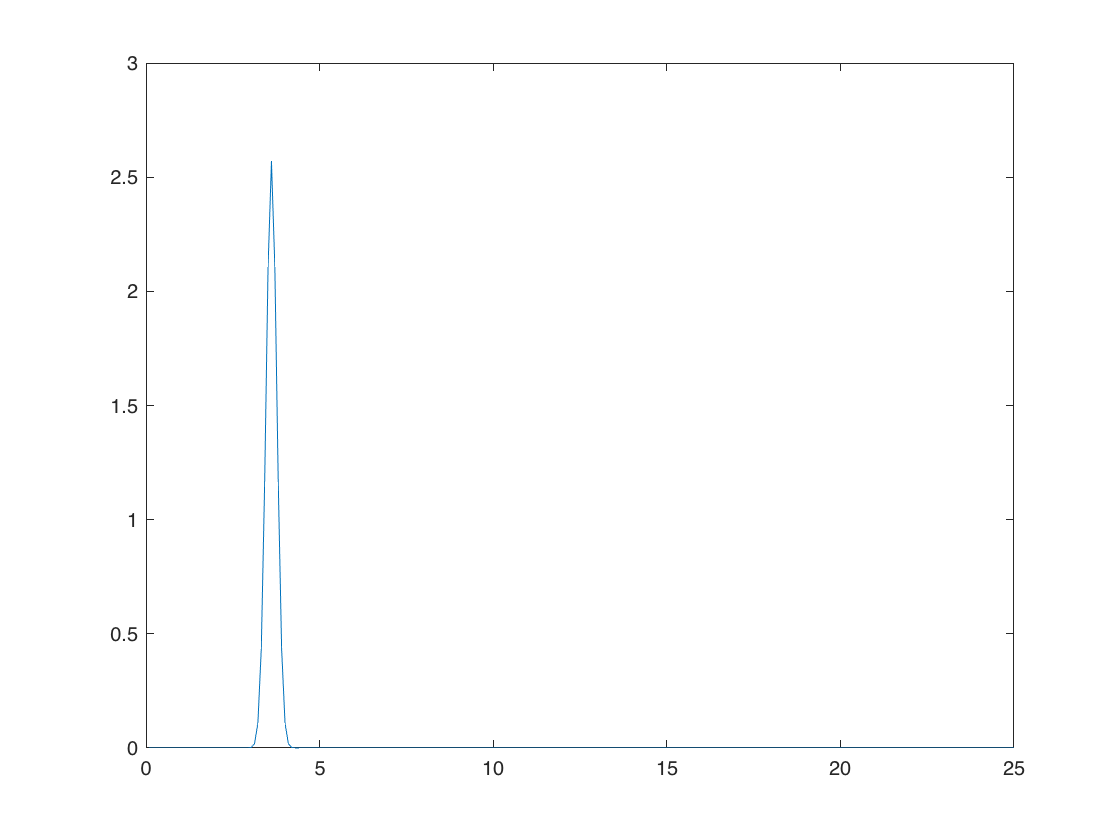

width=0.1554;
miu=3.6133;
x=1:1:256;
x=x*(25/256);
Gaussian_y=1/(width*sqrt(2*pi))*exp(-(x-miu).^2/(2*width^2));
figure
plot(x,Gaussian_y)

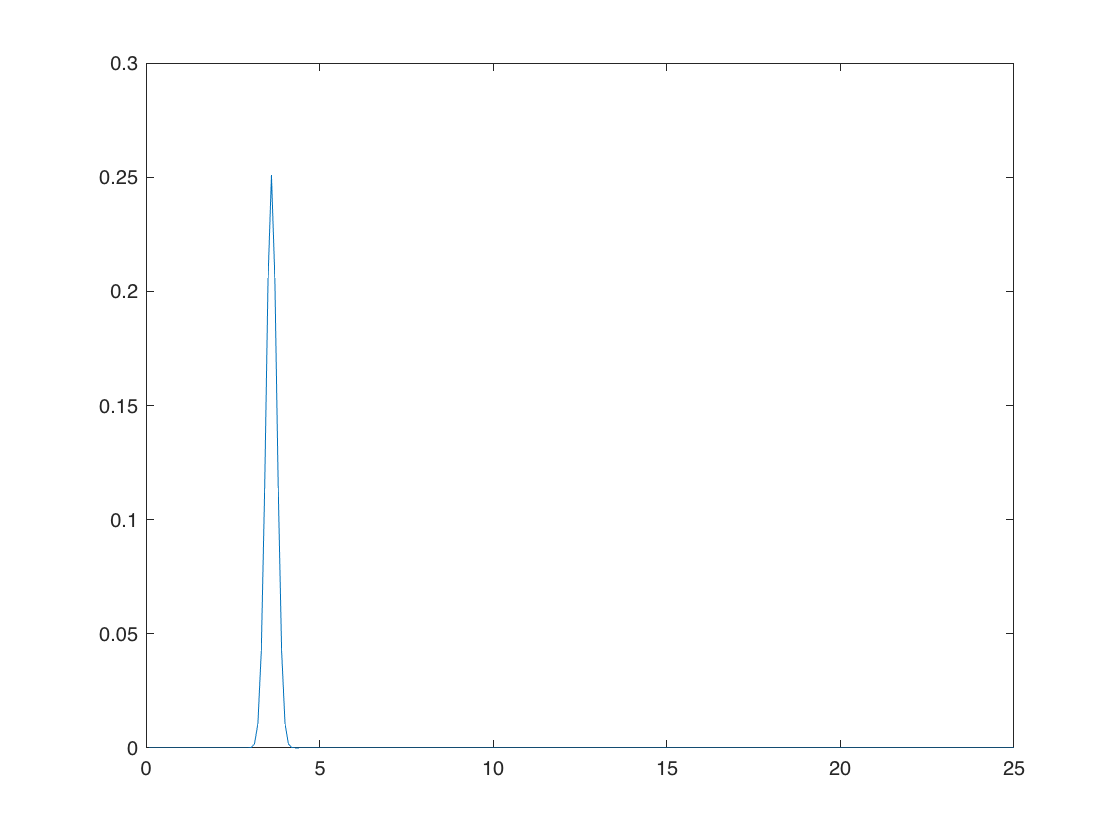


Gaussian_y=Gaussian_y/sum(Gaussian_y);
figure
plot(x,Gaussian_y)

% hold on
% plot(x,prf)
% legend('Gaussian','prf')

Gaussian_y=Gaussian_y';



AF=20000;
PopulationName='Simulation_20220326_autofluo_population';
% autofluo=KQ17_lifetimes/sum(KQ17_lifetimes);
global Gaussian_y

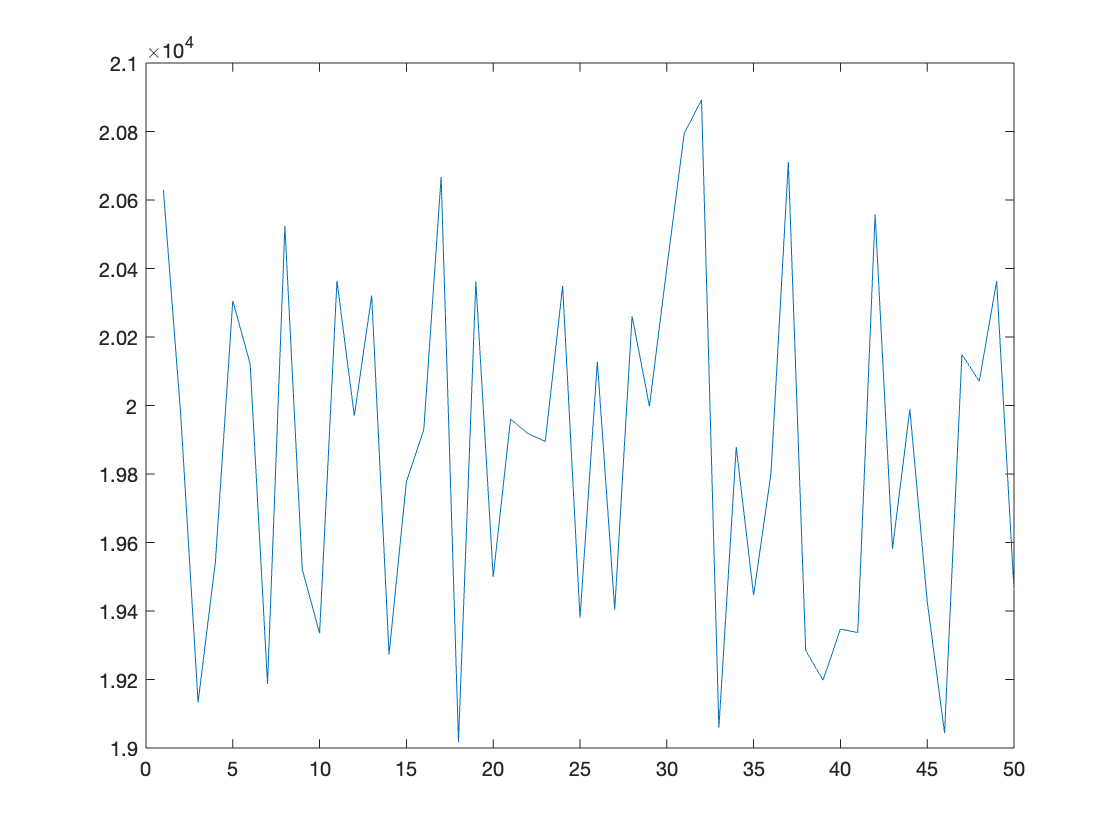

SS_all=zeros(1,50);

mkdir([num2str(AF),'_AF'])
for i=1:50
    SS=randi(2000)+19000; % 10% of fluctuation
    SS_all(i)=SS;
    samplename=[num2str(AF),'_AF/',num2str(i),'_auto.mat'];
    FLIMsim256_FLP(SS,AF,PopulationName,samplename)
end

figure
plot(SS_all)

p1_samples=0.6:0.02:1.0; % simulate the p1 range from 0.6 to 1.0
AF=20000;
tau1=2.706;
tau2=0.2613;

SS_samples=20000:20000:500000; % simulated sample size range from 20000 to 500000.

global Gaussian_y

for i=1:21
    p1=p1_samples(i);
    p2=1-p1;
    PopulationName=['Simulation_02102022_FLP_population_',num2str(p1),'.mat'];
    GenPop256_FLP(100000, p1, p2, tau1, tau2, PopulationName); 
    for j=1:25
        SS=SS_samples(j);
        mkdir([num2str(SS),'_',num2str(p1)])
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            FLIMsim256_FLP(SS,AF,PopulationName,samplename)
        end
    end
end


p1_samples=0.6:0.02:1.0;
AF=20000;
tau1=2.706;
tau2=0.2613;
ch=1;

SS_samples=20000:20000:500000;

for i=1:21
    p1=p1_samples(i);
 

    for j=1:25
        SS=SS_samples(j);
%         mkdir([num2str(SS),'_',num2str(p1),'_auto'])
        
        tau_avg=[];
        tau_avgTrunc=[];
        tau_empTrunc=[];
        photoncount=[];
        p1_sim=[];
        chi2=[];
        beta2=[];
        beta4=[];
        beta5=[];
        beta6=[];
        lifetime_histograms=[];
        peak_beforeC=[];
        peak_afterC=[];
        peak_withauto=[];
        
        for k=1:50
            
            AFname=['20000_AF/',num2str(k),'_auto.mat'];
            load(AFname);
            n_auto=n2';
            
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            load(samplename)
            n_ACh=n2';
            spc.lifetimes{1}=n_ACh+n_auto+6;
            
            
            spc_fitexp2gaussGY(ch);
%             spc_adjustTauOffset(1);
            
            
            photoncount(k)=sum(spc.lifetimes{1});
            p1_sim(k)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3);
            tau_avg(k)=spc.fits{ch}.avgTau; % mean Tau calculated from fit
            tau_avgTrunc(k)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k)=spc.fits{ch}.EmpTauTrunc;
            chi2(k)=spc.fits{ch}.redchisq;
            beta2(k)=spc.fits{ch}.beta2;
            beta4(k)=spc.fits{ch}.beta4;
            beta5(k)=spc.fits{ch}.beta5;
            beta6(k)=spc.fits{ch}.beta6;
            lifetime_histograms=[lifetime_histograms spc.lifetimes{1}];
            peak_beforeC(k)=mean(find(n1==max(n1)));
            peak_afterC(k)=mean(find(n2==max(n2)));
            peak_withauto(k)=mean(find(spc.lifetimes{1}==max(spc.lifetimes{1})));
            
        end
        
        photoncount=transpose(photoncount);
        tau_avg=transpose(tau_avg);
        tau_avgTrunc=transpose(tau_avgTrunc);
        tau_empTrunc=transpose(tau_empTrunc);
        p1_sim=transpose(p1_sim);
        chi2=transpose(chi2);
        beta2=transpose(beta2);
        beta4=transpose(beta4);
        beta5=transpose(beta5);
        beta6=transpose(beta6);
        
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        save(result_name,'photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1_sim','chi2','beta2','beta4','beta5','beta6','lifetime_histograms')
    end
end


cd('/Users/pingchuanma/Desktop/ChenLab_Data/simulation_FLP_20220326')
p1_samples=0.6:0.02:1.0;
AF=20000;
tau1=2.706;
tau2=0.2613;
ch=1;

SS_samples=20000:20000:500000;

for i=1:21
    p1=p1_samples(i);
    eval(['tau_empTrunc_',num2str(i),'=[];'])
    for j=1:25
        SS=SS_samples(j);
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(i),'=[tau_empTrunc_',num2str(i),' tau_empTrunc];'])
    end
end


for j=1:25
    SS=SS_samples(j);
    eval(['tau_empTrunc_',num2str(SS),'=[];'])
    
    for i=1:21
        p1=p1_samples(i);
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(SS),'=[tau_empTrunc_',num2str(SS),' tau_empTrunc];'])
    end
end


calculation of the mean and std of each condition of simulation

std_all=[];
mean_all=[];

for i=1:25
    SS=SS_samples(i);
    eval(['this_samplesize=tau_empTrunc_',num2str(SS),';'])
    std_all=[std_all;std(this_samplesize)];
    mean_all=[mean_all;mean(this_samplesize)];
end


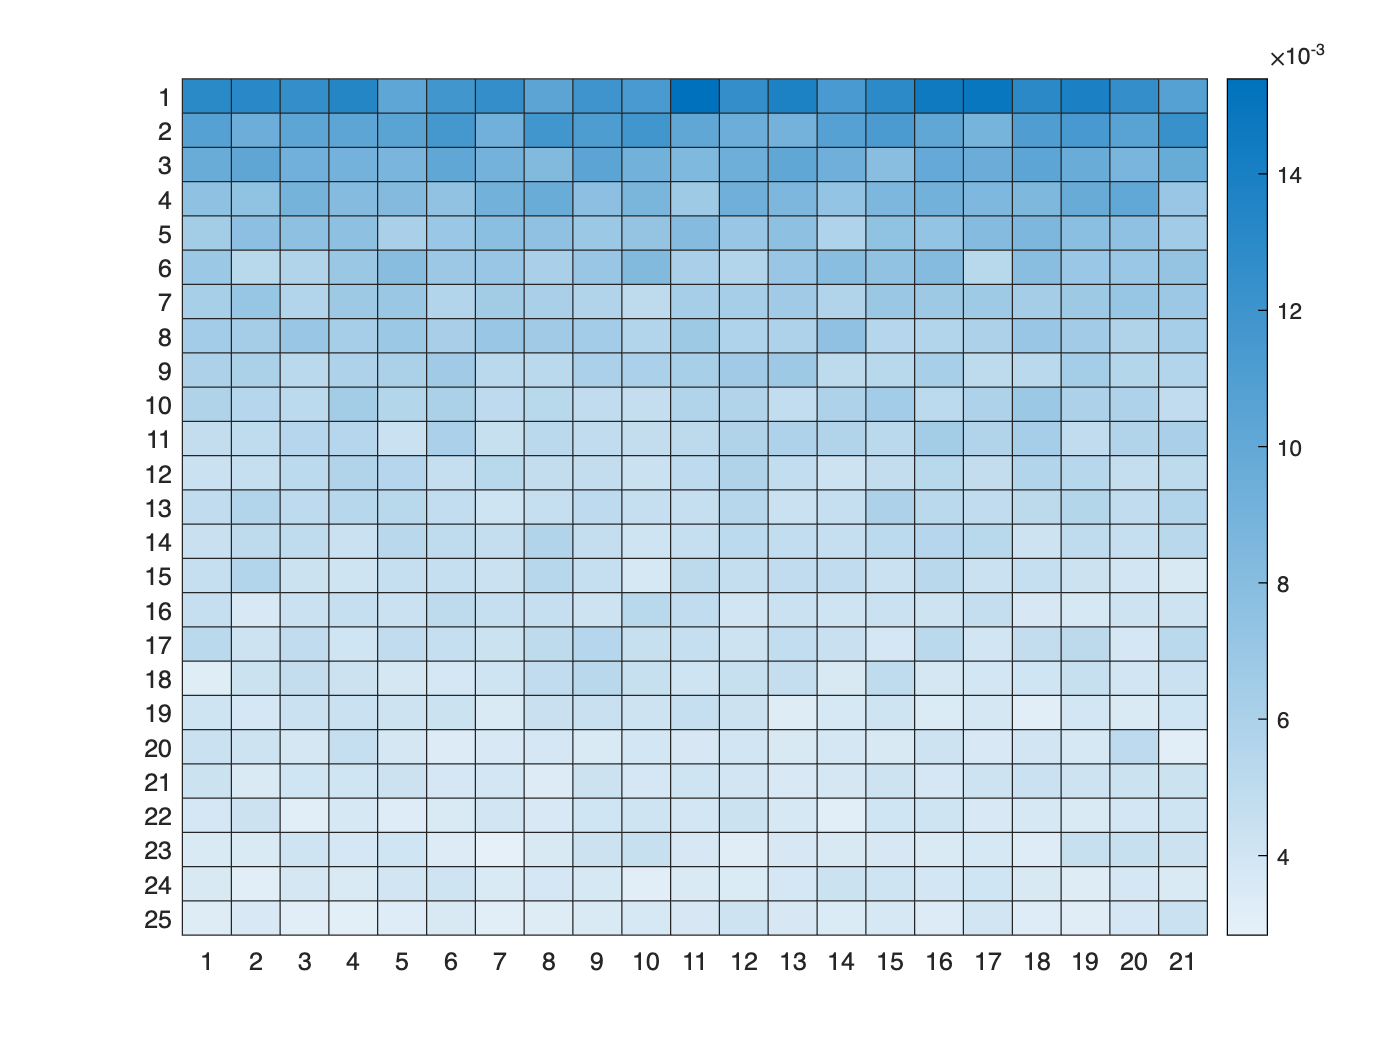

figure
heatmap(std_all)

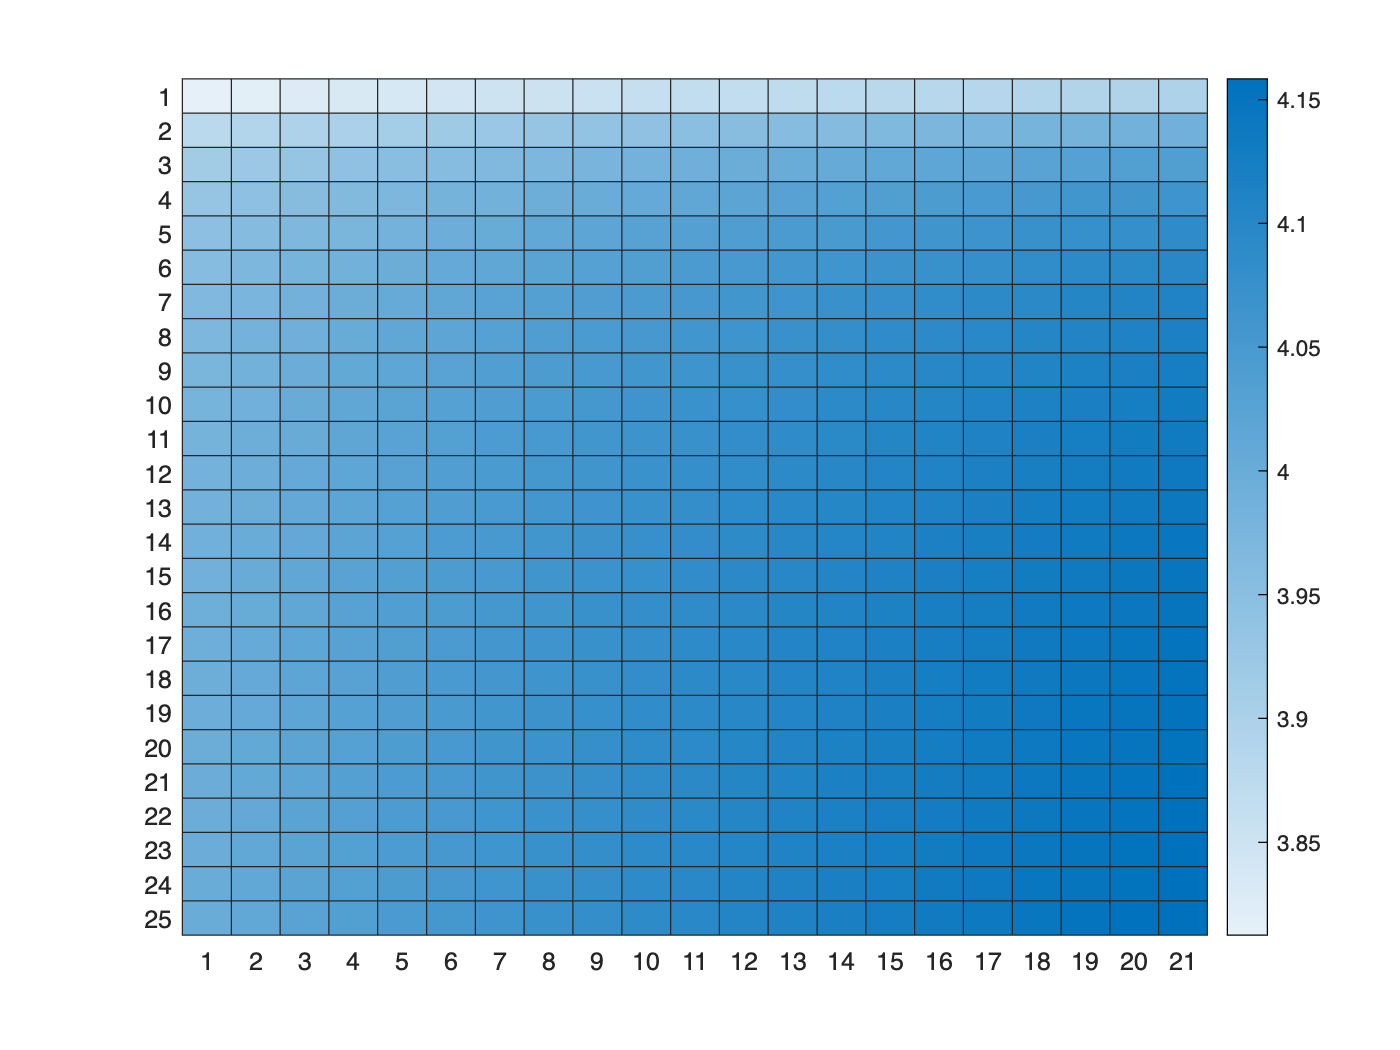


figure
heatmap(mean_all)

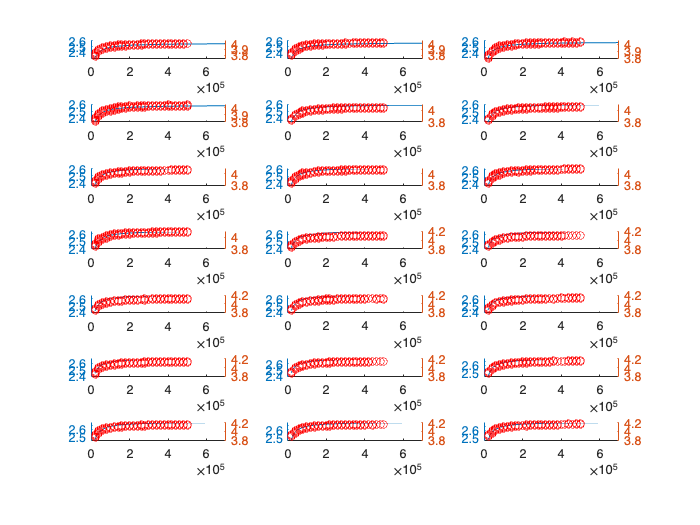

for j=1:21
    subplot(7,3,j)

    for i=1:25
        eval(['tau_empTrunc = tau_empTrunc_',num2str(j),';'])
        scatter_plot_x=zeros(50,1);
        scatter_plot_x=scatter_plot_x+SS_samples(i);
        yyaxis right
        scatter(scatter_plot_x,tau_empTrunc(:,i),'red');
        hold on
    end

    yyaxis left
    eval(['plot(sample_sizes, mean_lfts_',num2str(j),')'])
    hold off
end




% for i=1:25
%     scatter_plot_x=zeros(50,1);
%     scatter_plot_x=scatter_plot_x+SS_samples(i);
%     scatter(scatter_plot_x,tau_empTrunc_14(:,i),'green');
%     hold on
% end

for j=1:20
    mean_all_diff=zeros(25,21-j);
    for i=1:21-j
        mean_all_diff(:,i)=mean_all(:,i+j)-mean_all(:,i);
    end
    
    diff=mean_all_diff/3.96-std_all(:,1:(21-j));
    diff_plot=diff;
    diff_plot(find(diff>=0))=1;
    diff_plot(find(diff<0))=0;
    subplot(5,4,j)
    h=heatmap(diff_plot);
    h.Title=['p change = ',num2str(0.02*j)];
    h.ColorLimits=[0 1];
end

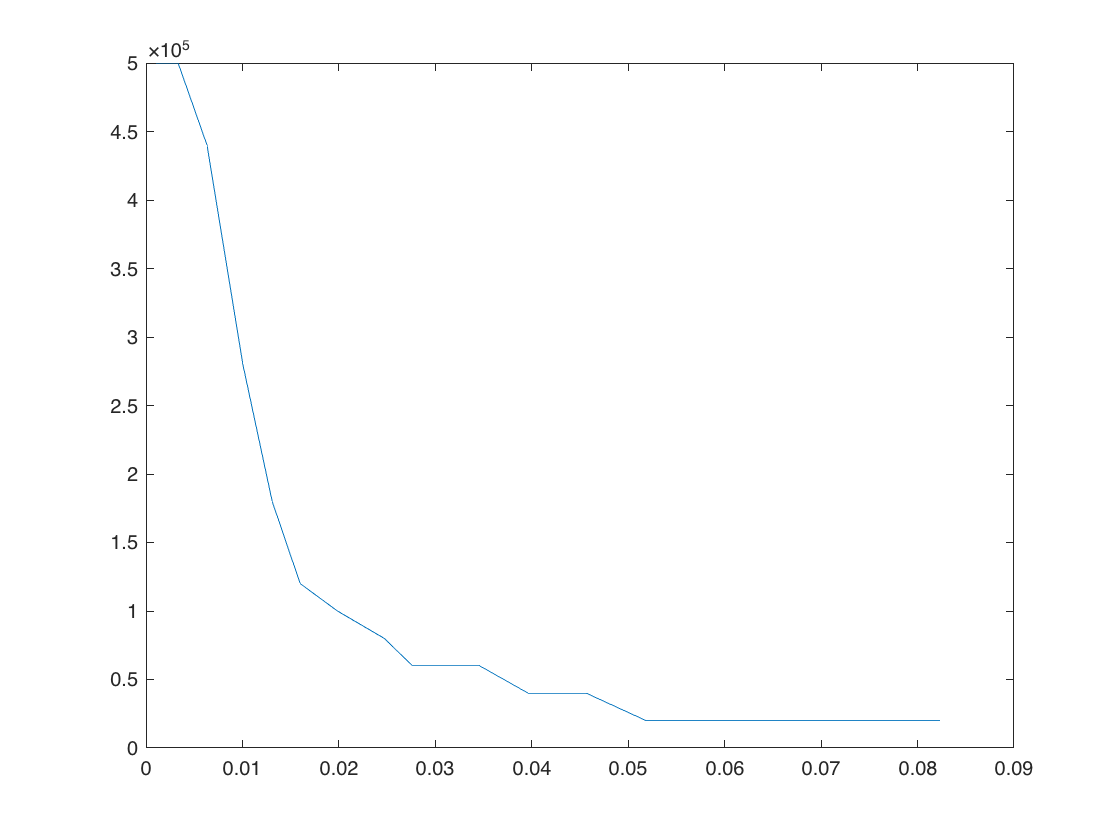

detectable_line=[25 25 22 14 9 6 5 4 3 3 3 2 2 2 1 1 1 1 1 1];
detectable_lft=zeros(1,20);

for j=1:20
    mean_all_diff=zeros(25,21-j);
    for i=1:21-j
        mean_all_diff(:,i)=mean_all(:,i+j)-mean_all(:,i);
    end
    
    
%         detectable_lft(j)=min(mean_all_diff(detectable_line(j),:));
          detectable_lft(j)=min(min(mean_all_diff));
    
    
%     subplot(5,4,j)
%     h=heatmap(mean_all_diff);
%     h.Title=['p change = ',num2str(0.02*j)];
%     h.ColorLimits=[0 0.1];
end

figure
plot(detectable_lft,SS_samples(detectable_line))

p1_samples=0.6:0.02:1.0;


SS_samples=20000:20000:500000;

for i=1:21
    p1=p1_samples(i);
 
    eval(['peaks_',num2str(i),'=[];'])
    for j=1:25
        SS=SS_samples(j);
        peaks=[];
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            load(samplename)
            n_ACh=n2';
            
            lifetimes=n_ACh;
            peaks=[peaks mean(find(lifetimes==max(lifetimes)))];
            
        end
        eval(['peaks_',num2str(i),'=[peaks_',num2str(i),'; peaks];'])
        
        
    end
    subplot(7,3,i)
    eval(['h=heatmap(peaks_',num2str(i),');'])
    h.ColorLimits=[37 41];
    h.Colormap=[0.5 0 0;1 0 0;0 0.5 0;0 1 0;0 0 1];
    h.XDisplayLabels=repmat(' ',50, 1);
    h.YDisplayLabels=repmat(' ',25,1);
    title(num2str(p1))

end

p1_samples=0.6:0.02:1.0;


SS_samples=20000:20000:500000;

for i=1:21
    p1=p1_samples(i);
 
    eval(['peaks_',num2str(i),'=[];'])
    for j=1:25
        SS=SS_samples(j);
        peaks=[];
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            load(samplename)
            n_ACh=n1';
            
            lifetimes=n_ACh;
            peaks=[peaks mean(find(lifetimes==max(lifetimes)))];
            
        end
        eval(['peaks_',num2str(i),'=[peaks_',num2str(i),'; peaks];'])
        
        
    end
    subplot(7,3,i)
    eval(['h=heatmap(peaks_',num2str(i),');'])
    h.ColorLimits=[37 41];
    h.Colormap=[0.5 0 0;1 0 0;0 0.5 0;0 1 0;0 0 1];
    h.XDisplayLabels=repmat(' ',50, 1);
    h.YDisplayLabels=repmat(' ',25,1);
    title(num2str(p1))

end

for j=1:24
    mean_all_diff2=zeros(25-j,21);
    for i=1:25-j
        mean_all_diff2(i,:)=mean_all(i+j,:)-mean_all(i,:);
    end
    diff=mean_all_diff2/3.96-std_all(1:25-j,:);
    diff_plot=diff;
    diff_plot(find(diff>=0))=1;
    diff_plot(find(diff<0))=0;
    subplot(6,4,j)
    h=heatmap(diff_plot);
    h.Title=['photon change = ',num2str(j*20000)];
    h.ColorLimits=[0 1];
end

detectable_line=[3 6 7 8 8 10 11 12 13 13];

photon_change=(1:1:10)*20000;
NoDetect_photons=SS_samples(detectable_line);
figure
plot(photon_change, NoDetect_photons)
xlabel('photon count change')
ylabel('photon count needed not to detect')

% Look at the phton count change insensitive range
k=1;
mean_all_pool=zeros(25-k, 21);
std_all_pool=zeros(25-k, 21);
for i=1:25-k
    for j=1:21
        mean_all_pool(i,j)=mean([mean_all(i,j) mean_all(i+k,j)]);
        std_all_pool(i,j)=sqrt(std_all(i,j)^2+std_all(i+k,j)^2);
    end
end

for j=1:20
    mean_all_pool_diff=zeros(25-k,21-j);
    for i=1:21-j
        mean_all_pool_diff(:,i)=mean_all_pool(:,i+j)-mean_all_pool(:,i);
    end
    
    diff=mean_all_pool_diff/3.96-std_all_pool(:,1:(21-j));
    diff_plot=diff;
    diff_plot(find(diff>=0))=1;
    diff_plot(find(diff<0))=0;
    subplot(5,4,j)
    h=heatmap(diff_plot);
    h.Title=['p change = ',num2str(0.02*j),'/photon change range = ',num2str(20000*k)];
    h.ColorLimits=[0 1];
end

k=10;
mean_all_pool=zeros(25-k, 21);
std_all_pool=zeros(25-k, 21);
for i=1:25-k
    for j=1:21
        mean_all_pool(i,j)=mean([mean_all(i,j) mean_all(i+k,j)]);
        std_all_pool(i,j)=sqrt(std_all(i,j)^2+std_all(i+k,j)^2);
    end
end

for j=1:20
    mean_all_pool_diff=zeros(25-k,21-j);
    for i=1:21-j
        mean_all_pool_diff(:,i)=mean_all_pool(:,i+j)-mean_all_pool(:,i);
    end
    
    diff=mean_all_pool_diff/3.96-std_all_pool(:,1:(21-j));
    diff_plot=diff;
    diff_plot(find(diff>=0))=1;
    diff_plot(find(diff<0))=0;
    subplot(5,4,j)
    h=heatmap(diff_plot);
    h.Title=['p change = ',num2str(0.02*j),'/photon change range = ',num2str(20000*k)];
    h.ColorLimits=[0 1];
end

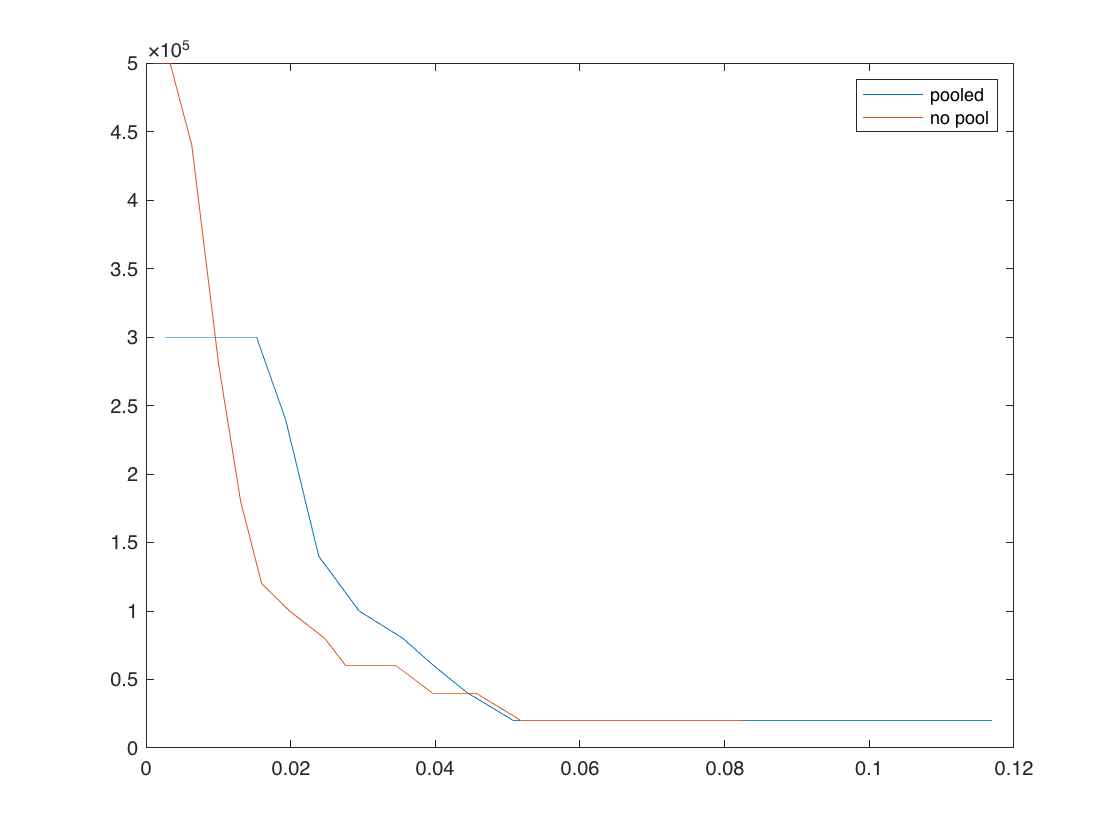

detectable_line_10=[15 15 15 15 12 7 5 4 3 2 1 1 1 1 1 1 1 1 1 1];
detectable_lft_10=zeros(1,20);

for j=1:20
    mean_all_pool_diff=zeros(25-k,21-j);
    for i=1:21-j
        mean_all_pool_diff(:,i)=mean_all_pool(:,i+j)-mean_all_pool(:,i);
    end
    if detectable_line_10(j)==25
        detectable_lft_10(j)=0;
    else
%         detectable_lft_10(j)=min(mean_all_pool_diff(detectable_line_10(j),:));
        detectable_lft_10(j)=min(min(mean_all_pool_diff));
    end
end

figure
plot(detectable_lft_10,SS_samples(detectable_line_10))
hold on
plot(detectable_lft,SS_samples(detectable_line))
legend('pooled','no pool')